# Derivacion Numerica

clear
clc
syms x
format long
f=exp(12*x)+x %funcion a aproximar

$$f = x+{\mathrm{e}}^{12\,x}$$

h = 0.1; %espaciado o tamaño de paso
xi = 1.2; %equis sub 0 o valor a evaluar en la derivada
hacia=input('Digite 1.hacia adelante - 2.centradas - 3.hacia atras: ');
deriv=input('Digite # derivada 1.primera - 2.segunda - 3.tercera - 4.cuarta: ');
valor_teorico = derivadan(f,deriv,xi)

$$der1 = 12\,{\mathrm{e}}^{12\,x}+1$$

valor_teorico =      2.152889827127457e+07


if     hacia==1 %adelante
    disp('Diferencias finitas hacia adelante =>')
    if     deriv==1
        valor_experimental = double((-subs(f,xi+2*h)+4*subs(f,xi+h)-3*subs(f,xi))/(2*h))
    elseif deriv==2
        valor_experimental = double((-subs(f,xi+3*h)+4*subs(f,xi+2*h)-5*subs(f,xi+h)+2*subs(f,xi))/(h^2))
    elseif deriv==3
        valor_experimental = double((-3*subs(f,xi+4*h)+14*subs(f,xi+3*h)-24*subs(f,xi+2*h)+18*subs(f,xi+h)-5*subs(f,xi))/(2*(h^3)))
    elseif deriv==4
        valor_experimental = double((-2*subs(f,xi+5*h)+11*subs(f,xi+4*h)-24*subs(f,xi+3*h)+26*subs(f,xi+2*h)-14*subs(f,xi+h)+3*subs(f,xi))/(h^4))
    end
elseif hacia==2 %centradas
    disp('Diferencias finitas centradas =><=')
    if     deriv==1
        valor_experimental = double((-subs(f,xi+2*h)+8*subs(f,xi+h)-8*subs(f,xi-h)+subs(f,xi-2*h))/(12*h))
    elseif deriv==2
        valor_experimental = double((-subs(f,xi+2*h)+16*subs(f,xi+h)-30*subs(f,xi)+16*subs(f,xi-h)-subs(f,xi-2*h))/(12*(h^2)))
    elseif deriv==3
        valor_experimental = double((-subs(f,xi+3*h)+8*subs(f,xi+2*h)-13*subs(f,xi+h)+13*subs(f,xi-h)-8*subs(f,xi-2*h)+subs(f,xi-3*h))/(8*(h^3)))
    elseif deriv==4
        valor_experimental = double((-subs(f,xi+3*h)+12*subs(f,xi+2*h)+39*subs(f,xi+h)+56*subs(f,xi)-39*subs(f,xi-h)+12*subs(f,xi-2*h)+subs(f,xi-3*h))/(6*(h^4)))
    end
elseif hacia==3 %atras   
    disp('Diferencias finitas hacia atras <=')
    if     deriv==1
        valor_experimental = double((3*subs(f,xi)-4*subs(f,xi-h)+subs(f,xi-2*h))/(2*h))
    elseif deriv==2
        valor_experimental = double((2*subs(f,xi)-5*subs(f,xi-h)+4*subs(f,xi-2*h)-subs(f,xi-3*h))/(h^2))
    elseif deriv==3
        valor_experimental = double((5*subs(f,xi)-18*subs(f,xi-h)+24*subs(f,xi-2*h)-14*subs(f,xi-3*h)+3*subs(f,xi-4*h))/(2*(h^3)))
    elseif deriv==4
        valor_experimental = double((3*subs(f,xi)-14*subs(f,xi-h)+26*subs(f,xi-2*h)-24*subs(f,xi-3*h)+11*subs(f,xi-4*h)-2*subs(f,xi-5*h))/(h^4))
    end  
else
    disp('@Valor invalido digitado!')
end

Diferencias finitas centradas =><=


valor_experimental =      1.976311495035385e+07


error_absoluto = abs(valor_teorico - valor_experimental)

error_absoluto =      1.765783320920724e+06


error_relativo=abs((valor_teorico-valor_experimental)/valor_teorico)

error_relativo =    0.082019214298428


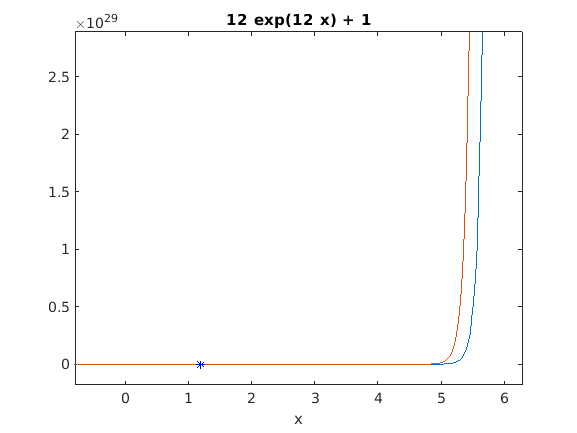

ezplot(f)
hold on
ezplot(diff(f))
hold on
plot(xi,valor_teorico,'r*')
plot(xi,valor_experimental,'b*')

function[t,e]=derivadan(f,deriv,xi)
    if deriv==1
        der1=diff(f,1)
        t = double(subs(diff(f,1),xi));
    elseif deriv==2
        der2=diff(f,2)
        t = double(subs(diff(f,2),xi));
    elseif deriv==3
        der3=diff(f,3)
        t = double(subs(diff(f,3),xi));
    elseif deriv==4
        der4=diff(f,4)
        t = double(subs(diff(f,4),xi));
    else
        disp('@Valor invalido digitado!')
    end
end